## Titanic Project (02/02/2021)

The Intro to Data Science module begins with an exercise looking at the famous "Titanic" dataset.

A generalised approach to data science challenges is outlined below:

- Questions are asked

- Data is acquired

- Data is prepared / pre-processed

- Data is analysed

- Findings are reported

- Question is answered (or repeat)

The tragedy of the Titanic is widely appreciated; however one may wish to know more about the distribution of survivors. For instance, were women and children more likely to have survived? And what about first-class passengers when compared to the rest? These form our questions for this task.

Data is supplied in the form of a CSV file which contains information about the passengers. In this case, we do not have full visibility over the means of data collection, so we will assume that the data was collected representatively from the 2224 actual passengers (from which 1500 died).

The data can be imported into MATLAB as a table to facilitate an initial screening.

data = readtable("./data/titanic.csv");

head(data,5)

ans = 5×8 table
    Survived    Pclass                             Name                                Sex        Age    Siblings_SpousesAboard    Parents_ChildrenAboard     Fare 
    ________    ______    ______________________________________________________    __________    ___    ______________________    ______________________    ______

       0          3       {'Mr. Owen Harris Braund'                            }    {'male'  }    22               1                         0                 7.25
       1          1       {'Mrs. John Bradley (Florence Briggs Thayer) Cumings'}    {'female'}    38               1                         0               71.283
       1          3       {'Miss. Laina Heikkinen'     

Taking an initial look at the table, the columns are as follows:

- Survived - indicating whether the passenger perished (0) or survived (1) - Binary Variable

- Pclass - indicating the passenger class (1 or 2 or 3) - Categorical Variable

- Name - indicating the name of the passenger (Forename + Surname combination) - Categorical Variable; theoretical infinite length

- Sex - indicating the sex of the passenger (male or female) - Categorical (Binary) Variable

- Age - indicating the age of the passenger - Continuous Numeric Variable

- Siblings_SpousesAboard - indicating the number of Siblings/Spouses (1,2,3...) - Discrete Numeric Variable

- Parents_ChildrenAboard - indicating the number of Parents/Children Aboard (1,2,3...) - Discrete Numeric Variable

- Fare - indicating the passenger fare / ticket price - Continuous Numeric Variable

Common sense dictates that there is likely little value in analysing the names column (expect from niche analysis exercises around survivors having a particular name), and so we can drop this column to reduce the size of our dataset. We will keep the others for now.

data = removevars(data,{'Name'});
% Note: alternative approach would have been data.Name = [];
head(data,5)

ans = 5×7 table
    Survived    Pclass       Sex        Age    Siblings_SpousesAboard    Parents_ChildrenAboard     Fare 
    ________    ______    __________    ___    ______________________    ______________________    ______

       0          3       {'male'  }    22               1                         0                 7.25
       1          1       {'female'}    38               1                         0               71.283
       1          3       {'female'}    26               0                         0                7.925
       1          1       {'female'}    35               1                         0                 53.1
       0          3       {'male'  }    35               0                         0                 8.05


Now, let's interrogate the values in each column to determine whether any pre-processing or data cleaning is required.

summary(data);

Variables:

    Survived: 887×1 double

        Properties:
            Description:  Survived
        Values:

            Min          0    
            Median       0    
            Max          1    

    Pclass: 887×1 double

        Properties:
            Description:  Pclass
        Values:

            Min          1    
            Median       3    
            Max          3    

    Sex: 887×1 cell array of character vectors

        Properties:
            Description:  Sex
    Age: 887×1 double

        Properties:
            Description:  Age
        Values:

            Min         0.42  
            Median        28  
            Max           80  

    Siblings_SpousesAboard: 887×1 double

        Properties:
            Description:  Siblings/Spouses Aboard
        Values:

            Min          0    
            Median       0    
            Max          8    

    Pa

According to the data summary, there are no missing values, so it likely that pre-processing of the data has already taken place. Further pre-processing could look at encoding values (e.g. one-hot encoding categorical variables, and binarising sex), however this is not strictly necessary for this investigation. Other interesting observations can be made from this information, such as the large family with 6 children in one case. However, to make this easier and get a more descriptive look at the data, we will make some plots.

Let's start by looking at overall statistics and the distribution of passengers according to our sample.

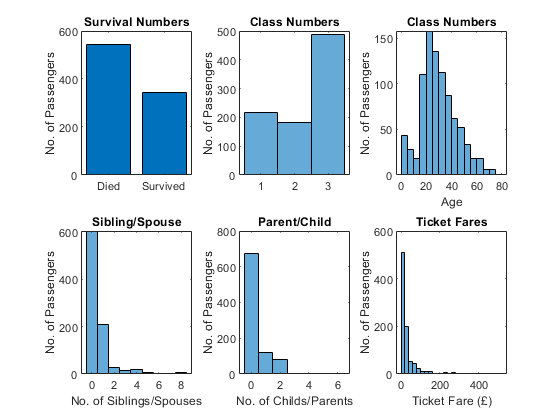

% Lets compare number of survivors to number of deaths - summary statistic
figure;
subplot(2,3,1);
noOfSurvivors = length(find(data.Survived==1));
noOfFatalities = length(find(data.Survived==0));
bar(categorical({'Died','Survived'}),[noOfFatalities, noOfSurvivors]);
ylabel('No. of Passengers');
title('Survival Numbers');


% Generating subplots to inform about passenger frequency per attribute

subplot(2,3,2);
histogram(data.Pclass);
ylabel('No. of Passengers');
title('Class Numbers');

subplot(2,3,3);
histogram(data.Age);
ylabel('No. of Passengers');
xlabel('Age');
title('Class Numbers');

subplot(2,3,4);
histogram(data.Siblings_SpousesAboard);
ylabel('No. of Passengers');
xlabel('No. of Siblings/Spouses');
title('Sibling/Spouse');

subplot(2,3,5);
histogram(data.Parents_ChildrenAboard);
ylabel('No. of Passengers');
xlabel('No. of Childs/Parents');
title('Parent/Child');

subplot(2,3,6);
histogram(data.Fare);
ylabel('No. of Passengers');
xlabel('Ticket Fare (£)');
title('Ticket Fares');

From this initial set of plots, we can see that approximately 1.5x as many people in the sample died than survived. This can be deemed a relatively good match to the roughly 2:1 ratio of deaths to survivals in the event, meaning our sample is likely fairly representative across these two classes (although it is hard to determine exactly without further information).

Class numbers shows a similar number of first- and second-class passengers, albeit a significant amount more in third class (making up around half of the dataset). This would be expected, with the expense and exclusivity of higher classes limiting their numbers. (A further investigation into ticket fares for the higher price could conducted to verify this).

Age appears to follow a skewed normal (bimodal) distribution, with most passengers aged 20-40, the largest peak being skewed towards the start of this range. This once again makes physical sense, with contextual information about the Titanic further supporting the prospect of a primarily adult audience. A smaller peak is observed to the far left of the plot, which would correspond with babies, who could be considered less disruptive to a family's decision to travel based on the lesser requirements to travel with a baby over a child.

The Parent/Child plot shows that most passengers travelled individually, accounting for two thirds of the data, which is likely justified by ticket prices forcing family travel to those who could afford it (a further investigation could similarly be conducted to verify this). A similar number of passengers were found to travel in a family with either 1 or 2 children, with the presumed higher earnings of households that could travel in a family likely being able to justify this extra expense.

The Sibling/Spouse plot shows some correlation with the Parent/Child plot, as would be expected, with more frequent cases of individual travellers, and fewer cases of larger groups and families. An example would be a family with 6 children, thereby contributing both to the Parent/Child data, and to the Sibling/Spouse data.

The ticket fare plot supports the previous observations for class number, showing a very high proportion of tickets at a low price (corresponding with 3rd class passengers), and a rapid drop-off in passenger numbers at higher ticket fares.

Now let's do some further plots and calculations to help answer some questions surrounding the risk of different passenger groups. To start with, lets define some sets of useful groups of passenger statistics.

% Fetching class data
first = find(data.Pclass == 1);
second = find(data.Pclass == 2);
third = find(data.Pclass == 3);

% Fetching sex data
male = find(string(data.Sex) == 'male');
female = find(string(data.Sex) == 'female');

% Fetching survival data
survived = find(data.Survived == 1);
died = find(data.Survived == 0);

Having defined these sets, we can consider some conditional probabilities and the resulting risk factors. For instance, what is the probability that you died, given you were a passenger on the titanic? Also, what was the probability of dying, given you were female?


$$Pr(A \mid B) = \frac{Pr(A \cap B)}{Pr(B)}$$


% Conditional probability for dying given being a passenger
% I.e. P(die)/P(die or survive)
P_died_passenger = length(died)/length(union(died,survived))

P_died_passenger = 0.6144

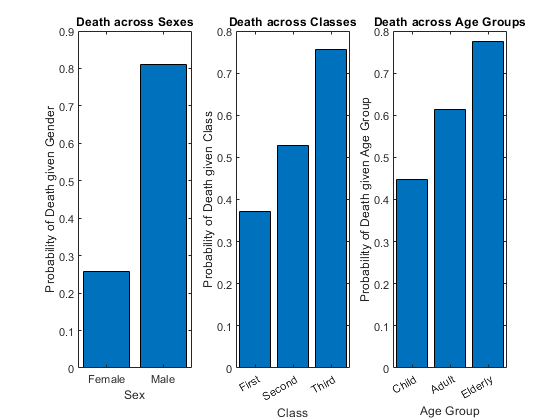

% Risk factor for females (Probability of dying given female)
P_died_female = length(intersect(died,female))/length(female);

% Risk factor for males (Probability of dying given male)
P_died_male = length(intersect(died,male))/length(male);

figure
subplot(1,3,1);
bar(categorical({'Female','Male'}),[P_died_female, P_died_male]);
xlabel('Sex');
ylabel('Probability of Death given Gender');
title('Death across Sexes');


% Risk factor for different classes:
P_died_third = length(intersect(died,third))/length(third);
P_died_second = length(intersect(died,second))/length(second);
P_died_first = length(intersect(died,first))/length(first);

subplot(1,3,2);
bar(categorical({'First','Second','Third'}),[P_died_first, P_died_second, P_died_third]);
xlabel('Class');
ylabel('Probability of Death given Class');
title('Death across Classes');


% Risk factor for children (under 16's)
% This is an example of basic feature engineering
children = find(data.Age < 16);
P_died_children = length(intersect(died,children))/length(children);
% Risk factor for mid-aged (16-60)
adults = union(find(data.Age >= 16), find(data.Age < 60));
P_died_adults = length(intersect(died,adults))/length(adults);
% Risk factor for elderly (over 60's)
elderly = find(data.Age >= 60);
P_died_elderly = length(intersect(died,elderly))/length(elderly);

subplot(1,3,3);
bar(reordercats(categorical({'Child','Adult','Elderly'}),{'Child','Adult','Elderly'}), ...
    [P_died_children, P_died_adults, P_died_elderly]);
xlabel('Age Group');
ylabel('Probability of Death given Age Group');
title('Death across Age Groups');

Investigating the Risk Factors and Conditional Probabilities gives results that would be expected in most cases. There appears to be a substantially higher probability of death if male as opposed to female, which is in line with what was expected with regards to prioritising the young and women. The chart of classes clearly illustrates a preference of saving those of higher class, with the conditional probability increasing as class decreases. Conditional probability of death also appears to increase with increasing age group, showing a tendency for the preservation of life. By combining these observations, it could be said that being an elderly male in the third class would put you in the highest risk group (from those investigated). However, as with all observations drawn from this dataset, they can only be claimed to hold for this specific data sample, and more information is required in order to draw population-wide conclusions.

For completeness, we will now verify some earlier assumptions with respect to correlation between class and ticket fare, and passenger class and family.

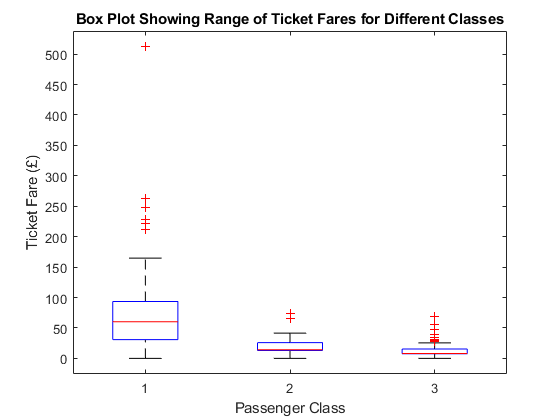

data_class_ticket = data(:,{'Pclass','Fare'});
figure;
boxplot(data_class_ticket.Fare, categorical(data_class_ticket.Pclass));
xlabel('Passenger Class');
ylabel('Ticket Fare (£)');
title('Box Plot Showing Range of Ticket Fares for Different Classes');

The box plot supports the previous assumption that the more exclusive classes generally cost more, partially explaining the disparity between the size of the classes. However, other interesting observations can be made around the consistency of ticket pricing. Third class appears to have been the most consistently priced, shown by a short box plot and closely banded whiskers, which both appear to grow with increasing exclusivity in class, showing greater variation in pricing, up to an extreme of over £500 for first class, despite a median of around £50 for even first class. Another interesting observation from this is the overlap in pricing between the classes, particularly the third and second class, with many individuals appearing to have paid more than their second part equivalent due to the close ticket fairs between these two classes. A reason for this could be last minute price-hiking, with people wanting to board the ship at any cost given the records it was predicted to break.

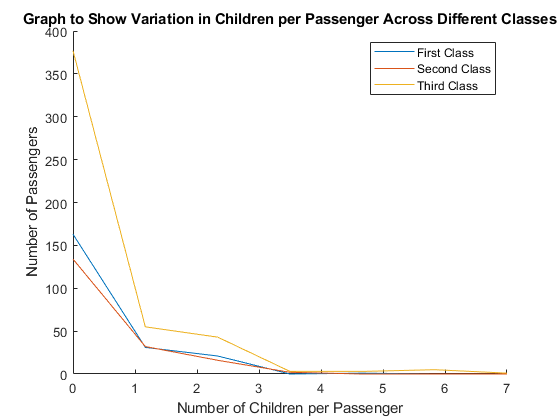

data_class_family = data(:,{'Pclass','Parents_ChildrenAboard'});

% Aim is to create a plot to show the variation in child-to-passenger ratio
% across different classes

% Start by finding the range of data
x_datarange = range(data.Parents_ChildrenAboard) + 1;

% Then extract Parent/Child data of target class
first_children = data(data.Pclass == 1,:).Parents_ChildrenAboard;

% And attribute to an accumulation table to track these occurences
[GC,GR] = groupcounts(first_children);
first_children_encoded = zeros(x_datarange,1);
for i=1:length(GR)
    first_children_encoded(GR(i)+1) = GC(i);
end

% Repeat for other classes
second_children = data(data.Pclass == 2,:).Parents_ChildrenAboard;
[GC,GR] = groupcounts(second_children);
second_children_encoded = zeros(x_datarange,1);
for i=1:length(GR)
    second_children_encoded(GR(i)+1) = GC(i);
end

third_children = data(data.Pclass == 3,:).Parents_ChildrenAboard;
[GC,GR] = groupcounts(third_children);
third_children_encoded = zeros(x_datarange,1);
for i=1:length(GR)
    third_children_encoded(GR(i)+1) = GC(i);
end

% Generate plot
figure;
x_range = linspace(min(data.Parents_ChildrenAboard),x_datarange,x_datarange);
hold on
plot(x_range, first_children_encoded);
plot(x_range, second_children_encoded);
plot(x_range, third_children_encoded);
legend('First Class','Second Class', 'Third Class')
xlabel('Number of Children per Passenger');
ylabel('Number of Passengers');
title('Graph to Show Variation in Children per Passenger Across Different Classes');
hold off

This graph contradicts the initial hypothesis made surrounding the child-to-passenger ratio across the different classes, and hence was an insightful plot to produce, initially believing that larger families would be those in the higher classes, as they could afford this. However does not appear to be the case, with the highest child-to-passenger ratio consistently occurring in the less exclusive passenger classes, and in the extreme cases, having passengers with 5 or even 6 children in the third class. In retrospect, this makes sense, as bringing additional passengers would amount to an additional expense, which could be restricted by going for a cheaper fare, and a less exclusive class (regardless of household income).